# GENAVA INDEXING MECHANISM 10mm retaining ring

## Symbolic Mathematics simulation

close all
Rot = @(theta)[cos(theta), -sin(theta); 
    sin(theta), cos(theta)];
Plot = @(dat, w) plot(dat(1,:), dat(2,:), 'k', 'LineWidth', w);
Fill = @(dat, clr) fill(dat(1,:), dat(2,:), clr);

## First slot

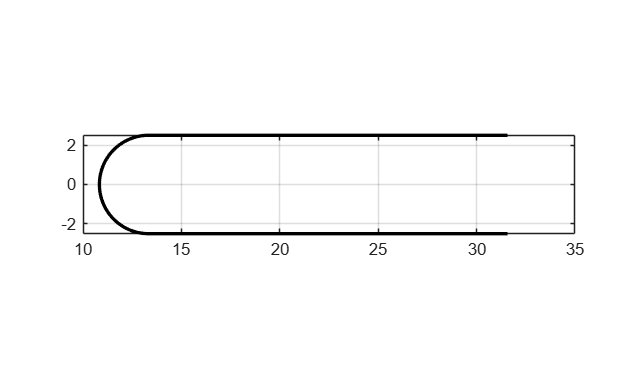

t = (270:-1:90)*pi/180;
data0 = [13.333 + [18.239, 0, 2.5*cos(t), 0, 18.239];
    -2.5,-2.5,2.5*sin(t), 2.5, 2.5];
idg = [1, size(data0, 2)];
Plot(data0, 2); daspect([1,1,1]); 
grid on;

## Copies of slots

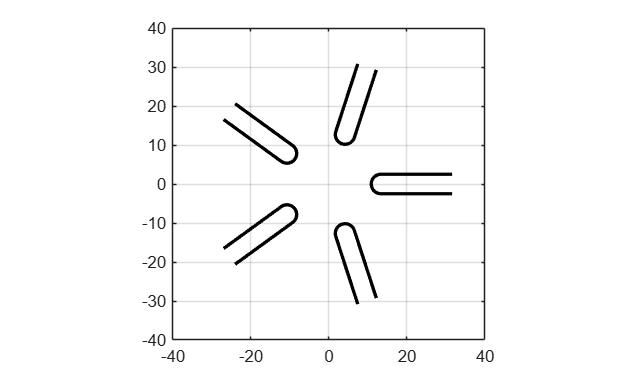

Nslots = 5; sR = 19.867;
Plot(data0, 2); hold on; daspect([1,1,1]); 
for n = 1:Nslots-1
    datan = Rot(2*n*pi/Nslots)*data0;
    Plot(datan, 2); 
end
hold off;
grid on;

## Add circumference

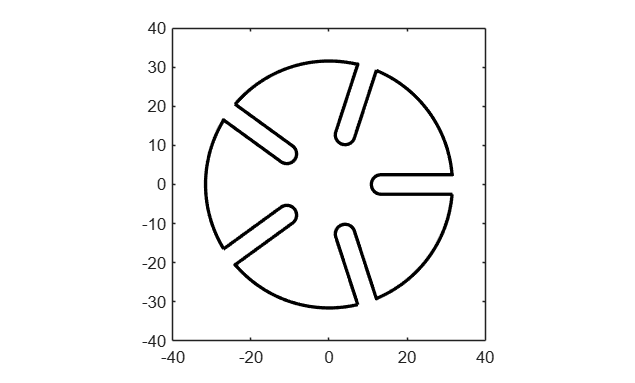

r = asin(2.5/31.572);
t = linspace(r, 2*pi/Nslots - r);
data2 = [data0, 31.572*[cos(t); sin(t)]];
idg = [idg, size(data2, 2)];
Plot(data2, 2); hold on; daspect([1,1,1]); 
for n = 1:Nslots-1
    datan = Rot(2*n*pi/Nslots)*data2;
    Plot(datan, 2); 
end
hold off;

## Add a the small circle

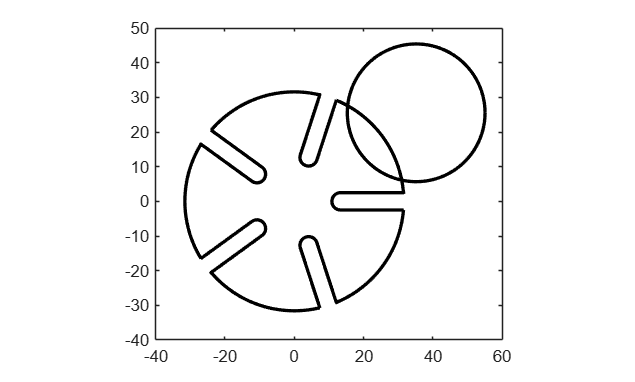

Plot(data2, 2); hold on; daspect([1,1,1]); 
for n = 1:Nslots-1
    datan = Rot(2*n*pi/Nslots)*data2;
    Plot(datan, 2); 
end
c = 43.441*[cos(pi/Nslots); sin(pi/Nslots)];
t = linspace(0, 2*pi);
SmallC = [c(1) + sR*cos(t); c(2) + sR*sin(t)];
Plot(SmallC, 2);
hold off;

## Add the intersecting part of small circle to big gear

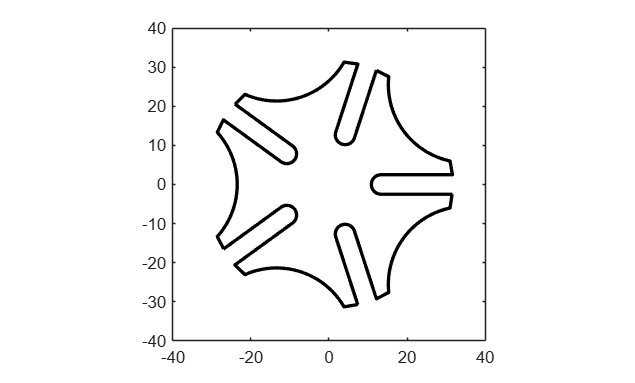

pts = CurveIntersection(data2, SmallC);
smlt = atan2(pts(2,:)-c(2), pts(1,:)-c(1));
smArc = fliplr(smallArc(smlt(1),...
    smlt(2), c, sR+0.1));
data3 = [data0, smArc, ...
    31.572*[cos(2*pi/Nslots - r); sin(2*pi/Nslots - r)]];
idg = [idg, size(data0, 2)+1, size(data3, 2)-1, size(data3, 2)];
Plot(data3, 2); hold on; daspect([1,1,1]); 
for n = 1:Nslots-1
    datan = Rot(2*n*pi/Nslots)*data3;
    Plot(datan, 2); 
end
hold off;

## Add the intersecting part of big circle to small circle

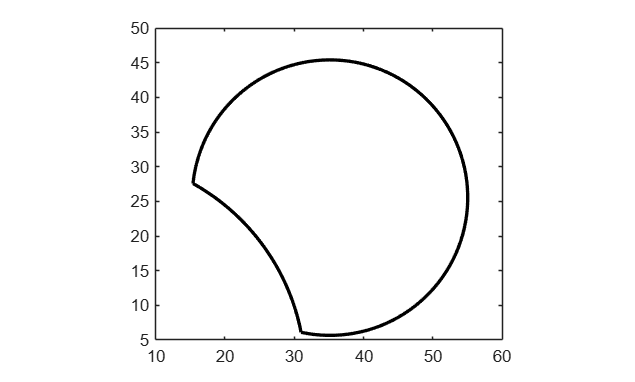

bgArc = fliplr(bigArc(smlt(1), smlt(2), c, sR));
bigt = atan2(pts(2,:), pts(1,:));
t = linspace(bigt(1), bigt(2));
Plot(bgArc, 2);  hold on; 
Plot(31.572*[cos(t); sin(t)], 2);  daspect([1,1,1]); 
hold off;

## Combine them together

ptc =  [bgArc, 32*[cos(t); sin(t)]];
IDS = [1, size(bgArc, 2)];
ptg = []; slots = []; IDG = [];
for n = 1:Nslots
    a = 2*(n + 0.5)*pi/Nslots;
    datan = Rot(a)*data3;
    ptg = [ptg, datan]; 
    slots = [slots,12*[cos(a); sin(a)]];
    IDG = [IDG, idg + (n-1)*idg(end)];
end
t = linspace(0, 2*pi);
unitc = [cos(t); sin(t)];

## Teardrop shape

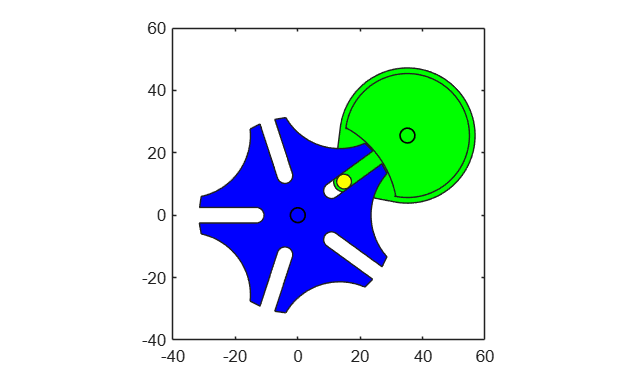

pts = 2.367*unitc;
pinc = 18.333*[cos(pi/Nslots);sin(pi/Nslots)];
% Teardrop Shape Coordinates
C1 = c;                      % Crank center [x; y]
R1 = 21.667;                 % Large disk radius
R2 = 3.333;                  % Pin tip fillet radius
C2 = pinc;                   % Pin center (distance 30.00 mm)

vec = C2 - C1;
d_len = norm(vec);
dir_ang = atan2(vec(2), vec(1));
alpha = acos((R1 - R2) / d_len);

% Generate boundary arcs for the large circle and pointed tip circle
t1_upper = dir_ang + alpha;
t1_lower = dir_ang - alpha;
t_main = linspace(t1_upper, t1_lower + 2*pi, 100);
arc_main = C1 + R1 * [cos(t_main); sin(t_main)];

t_tip = linspace(t1_lower, t1_upper, 30);
arc_tip = C2 + R2 * [cos(t_tip); sin(t_tip)];

teardrop = [arc_main, arc_tip];

Driver = Fill(teardrop, 'g'); hold on;

daspect([1 1 1]);
axis([-40,60,-40,60]);    
Gear = Fill(ptg, 'b');  
CutCircle = Fill(ptc, 'g');  daspect([1,1,1]); 
Plot(pts, 1); 
Plot([pts(1,:)+c(1);pts(2,:)+c(2)], 1);
pin = Fill([pts(1,:)+pinc(1); ...
    pts(2,:)+pinc(2)], 'y');
hold off;

## Lock the mechanism and Rotate

for n = 1:1400
    pinc = RotateAbout(pinc, -0.05, c);
    pin.XData = pts(1,:)+pinc(1); 
    pin.YData = pts(2,:)+pinc(2);

    teardrop = RotateAbout(teardrop, -0.05, c);
    Driver.XData = teardrop(1,:);
    Driver.YData = teardrop(2,:);

    ptc = RotateAbout(ptc, -0.05, c);
    CutCircle.XData = ptc(1,:); 
    CutCircle.YData = ptc(2,:); 

    %check if locked
    if(norm(pinc) < 31.572)
        %find slot the pin is
        xx = slots(1,:)-pinc(1);
        yy = slots(2,:)-pinc(2);
        dd = vecnorm([xx;yy]);
        [mind, id] = min(dd);
        %% compute the angle between them
        v = slots(:, id);
        cc = cross([v;0], [pinc;0]);
        ang = asin(cc(3)/(norm(v)*norm(pinc)));
        %% rotate gear
        ptg = RotateAbout(ptg, ang);
        Gear.XData = ptg(1,:); 
        Gear.YData = ptg(2,:); 
        slots = RotateAbout(slots, ang);
    end
    drawnow
end

## functions

function [bl, pt] = Intersect(a, b, x, y)
pt = [nan, nan];
den0 = (b(1) - a(1)) * (x(2) - y(2)) - (b(2) - a(2)) * (x(1) - y(1));
num1 = (x(1) - y(1)) * (a(2) - x(2)) - (x(2) - y(2)) * (a(1) - x(1));
num2 = (a(1) - x(1)) * (b(2) - a(2)) - (a(2) - x(2)) * (b(1) - a(1));
num1 = num1*(abs(num1) > 1e-10); num2 = num2*(abs(num2) > 1e-10);
s = num1 / den0; t = num2 / den0; bl = (0 < s && s < 1) && (0 < t && t < 1);
if(bl)
    pt = a+s*(b-a);
end
end

function pts = CurveIntersection(Curve1, Curve2)
pts = [];
for n = 2:size(Curve1,2)
    a = Curve1(:, n-1); b = Curve1(:, n); 
    for m = 2:size(Curve2,2)
        x = Curve2(:, m-1); y = Curve2(:, m);
        [bl, pt] = Intersect(a, b, x, y);
        if(bl)
            pts = [pts, pt];
        end
    end
end
end

function pts = smallArc(t1, t2, c, r)
t = linspace(t1, t2);
pts = [c(1)+ r*cos(t);  c(2) + r*sin(t)];
a = arcLength(pts)/r;
if(a > pi)
    t = linspace(t2, t1+2*pi);
    pts = [c(1)+ r*cos(t);  c(2) + r*sin(t)];
end
end

function pts = bigArc(t1, t2, c, r)
t = linspace(t1, t2);
pts = [c(1)+ r*cos(t);  c(2) + r*sin(t)];
a = arcLength(pts)/r;
if(a < pi)
    t = linspace(t2, t1+2*pi);
    pts = [c(1)+ r*cos(t);  c(2) + r*sin(t)];
end
end

function L = arcLength(pts)
d = diff(pts, 1, 2);
l = vecnorm(d);
L = sum(l);
end

function data = RotateAbout(data, theta, c)
if nargin < 3
    c = [0;0];
end
data = [cos(theta), -sin(theta); sin(theta), cos(theta)]*[data(1,:)-c(1); data(2,:)-c(2)];
data = [data(1,:)+c(1); data(2,:)+c(2)];
end

